# The Abelson model and the community cleavage problem

The continuous-time counterpart of French-DeGroot,

obtained by letting the time between opinion updates become infinitesimal.

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

NDS opinion-dynamics library added to the path.
Project root: /Users/llp/Desktop/NDS_Project


## Always convergent

L is a singular M-matrix: the zero eigenvalue is semisimple and every other eigenvalue has strictly positive real part. So exp(-Lt) always converges, and consensus holds exactly when the graph is rooted (Theorem 16).

Note that A need NOT be row-stochastic here -- the row sums are free and set how fast each agent is pulled towards its neighbours.

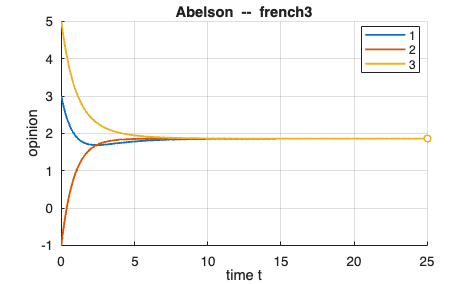

net = make_example_french3();
res = sim_abelson(net, [3; -1; 5], linspace(0, 25, 300));
figure; plot_opinions(res);


q = laplacian_power(net.A);
fprintf('Laplacian social power : %s\n', mat2str(round(q.', 6)));

Laplacian social power : [0.285714 0.428571 0.285714]


fprintf('p''L (should be zero)   : %s\n', mat2str(round(q.' * net.L, 12)));

p'L (should be zero)   : [0 0 0]


## Periodicity is a discrete-time artefact

The same directed ring that oscillates forever under French-DeGroot converges under Abelson. This is the single cleanest structural contrast between the two models.

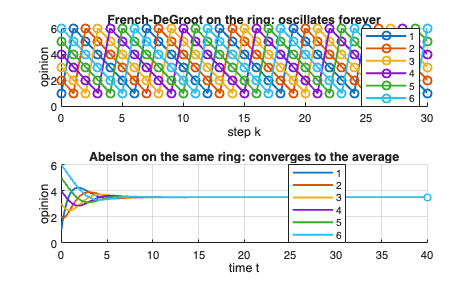

ring = make_ring(6);
x0 = (1:6).';

figure;
tl = tiledlayout(2, 1);
plot_opinions(sim_degroot(ring, x0, 30), 'Axes', nexttile(tl), ...
    'Title', 'French-DeGroot on the ring: oscillates forever');
plot_opinions(sim_abelson(ring, x0, linspace(0, 40, 300)), 'Axes', nexttile(tl), ...
    'Title', 'Abelson on the same ring: converges to the average');

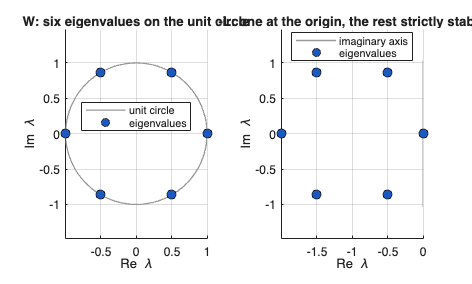


figure;
tl2 = tiledlayout(1, 2);
plot_spectrum(ring.W,  'Axes', nexttile(tl2), 'Title', 'W: six eigenvalues on the unit circle');
plot_spectrum(-ring.L, 'Domain', 'continuous', 'Axes', nexttile(tl2), ...
    'Title', '-L: one at the origin, the rest strictly stable');

## Sampling the flow recovers a DeGroot model (Lemma 17)

W_tau = exp(-tau*L) is row-stochastic with a POSITIVE DIAGONAL, so the sampled Abelson flow is automatically an aperiodic French-DeGroot model. That is precisely why no amount of sampling can make the continuous model oscillate.

tau = 0.35;
Wtau = expm(-ring.L * tau);
fprintf('W_tau row-stochastic  : %d\n', is_row_stochastic(Wtau, 1e-12));

W_tau row-stochastic  : 1


fprintf('positive diagonal     : %d\n', all(diag(Wtau) > 0));

positive diagonal     : 1



K = 40;
sampled = sim_degroot(Wtau, x0, K, 'Predict', false);
flow    = sim_abelson(ring, x0, tau * (0:K));
fprintf('max |sampled - flow|  : %.3e\n', max(abs(sampled.X(:) - flow.X(:))));

max |sampled - flow|  : 0.000e+00


## The Euler discretisation and its step-size condition

The other way to discretise is explicit Euler, x(k+1) = (I - eps*L) x(k). The result is row-stochastic exactly when eps * max_i (row sum of A) <= 1. Beyond that bound the weights go negative and the interpretation collapses.

comm = make_two_communities(4, 0.3);
maxDegree = max(sum(comm.A, 2));
fprintf('\ncritical step size: %.4f\n', 1 / maxDegree);


critical step size: 0.3030



for factor = [0.5 0.9 1.0 1.5]
    epsilon = factor / maxDegree;
    Weuler = eye(comm.n) - epsilon * comm.L;
    fprintf('eps = %.3f x critical : row-stochastic %d, min entry %+.3f\n', ...
        factor, is_row_stochastic(Weuler, 1e-12), min(Weuler(:)));
end

eps = 0.500 x critical : row-stochastic 1, min entry +0.000
eps = 0.900 x critical : row-stochastic 1, min entry +0.000
eps = 1.000 x critical : row-stochastic 1, min entry +0.000
eps = 1.500 x critical : row-stochastic 0, min entry -0.500


## Abelson's diversity puzzle

Abelson asked what one must assume in order to reproduce the persistent disagreement that empirical community studies report, given that consensus is the ubiquitous outcome of this whole class of models.

THE LINEAR ABELSON MODEL DOES NOT ANSWER IT. On a rooted graph it provably reaches consensus. Disagreement appears only when rootedness FAILS -- that is, when the network has two or more closed strong components, which means the group is really two groups. Disagreement is a topological accident, not a behavioural property.

split = make_two_communities(4, 0);
graph_report(split.W);

Graph report (8 agents)
  strong components : 2
    #1 [CLOSED] period=1 : [5 6 7 8]
    #2 [CLOSED] period=1 : [1 2 3 4]
  rooted            : no
  convergent        : yes
  reaches consensus : no
  -> several closed components: opinions settle into BLOCKS.


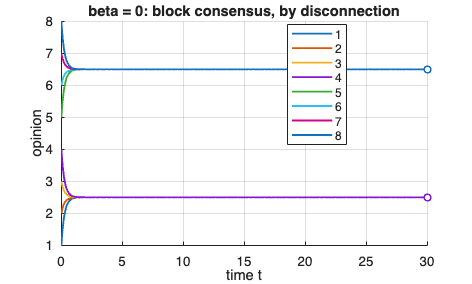

resSplit = sim_abelson(split, (1:split.n).', linspace(0, 30, 300));
figure; plot_opinions(resSplit, 'Title', 'beta = 0: block consensus, by disconnection');

## Weak coupling: consensus, but slowly

Restoring a single weak bridge restores rootedness and hence consensus -- but with a TIMESCALE SEPARATION, visible as a plateau on the log axis. Keep this figure in mind: the Friedkin-Johnsen model produces a superficially similar picture by a completely different mechanism, and telling the two apart is the subject of the comparative notebook.

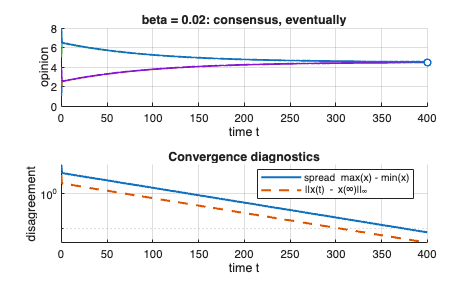

joined = make_two_communities(4, 0.02);
resJoined = sim_abelson(joined, (1:joined.n).', linspace(0, 400, 800));

figure;
tl3 = tiledlayout(2, 1);
plot_opinions(resJoined, 'Axes', nexttile(tl3), 'Legend', false, ...
    'Title', 'beta = 0.02: consensus, eventually');
plot_convergence(resJoined, 'Axes', nexttile(tl3));